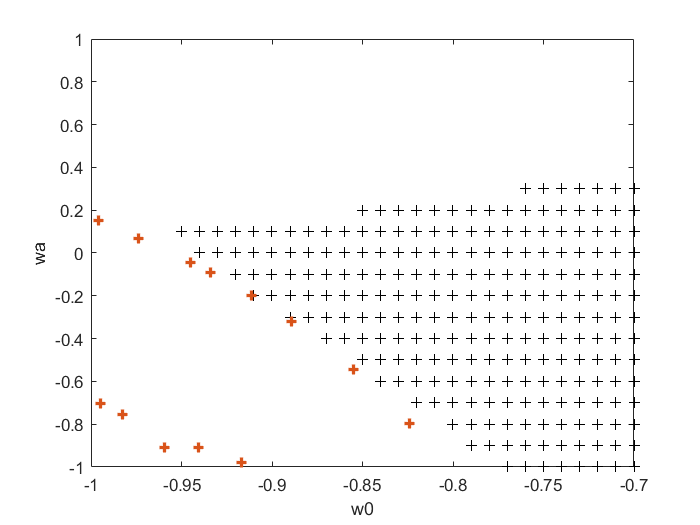

w00=[-1:0.01:-0.7];
for p=1:31
    w0=w00(p);
    wa=[-1:0.1:1];
    for i=1:21
        [N,O] = ode45(@(t,y) -3*(w0+wa(i)*(1-exp(t)))*y*(1-y),[0,log(0.5)] , 0.7);
        w=(w0+wa(i)*(1-exp(N))).*O;
        a=exp(N);
        [N_r,O_r] = ode45(@(t,y) -3*(w0+wa(i)*(1-exp(t)))*y*(1-y),[0,log(2)] , 0.7);
        w_r=(w0+wa(i)*(1-exp(N_r))).*O_r;
        a_r=exp(N_r);
    
        num=size(N,1);
        for k=1:num-1
            zeta(1)=0.00214;
            zeta(k+1)=zeta(k)+(N(k+1)-N(k))*(zeta(k)^2+3/2*(w(k)-1)*zeta(k)-9/4*(1+3*w(k)));
        end
        %num_r=size(Ndate_r,2);
        %for i=1:num_r-1
        %    zeta_r(k,1)=0.00614;
        %    zeta_r(k,i+1)=zeta_r(k,i)+(Ndate_r(k,i+1)-Ndate_r(k,i))*(zeta_r(k,i)^2+3/2*(wdate_r(k,i)-1)*zeta_r(k,i)-9/4*(1+3*wdate_r(k,i)));
        %end
        all_greater_than_minus_one = all(w(:) > -1);
        all_greater_than_minus_one_r = all(w_r(:) > -1);
        F=9/2*(1+w);
        if all_greater_than_minus_one
            if all_greater_than_minus_one_r
            if zeta(end)>-F(end)
                plot(w0,wa(i),'+k');
                axis([-1,-0.7,-1,1])
                hold on
                xlabel('w0')
                ylabel('wa')
            end
        end
    end
    end
end
datax=[-1.2015 -1.1795 -1.1619 -1.1135 -1.078  -1.0574 -1.0365 -0.9958 -0.9738 -0.9452 -0.9342 -0.9111 -0.8891 -0.855  -0.8242 -1.2147 -1.2048 -1.1905 -1.1685 -1.1432 -1.1333 -1.1025 -1.0794 -1.0486 -1.0189 -0.9947 -0.9826 -0.9595 -0.9408 -0.9166];
datay=[0.6538  0.6468  0.6153  0.5173  0.4263  0.3738  0.2968  0.1533  0.0693  -0.0427 -0.0917 -0.2002 -0.3192 -0.5432 -0.7952 0.5278  0.3948  0.3003  0.1638  0.0203  -0.0357 -0.2002 -0.3192 -0.4662 -0.6027 -0.7042 -0.7567 -0.9107 -0.9107 -0.9807];
plot(datax,datay,'+','Color','#D95319','LineWidth',2)